# PROYECTO ECUACIONES DIFERENCIALES.

## Integrantes.

- Harrison Esteban Boada Aldana

- Johan Santiago Ayala osorio.

- Yennifer Tatiana Boyaca suan.

## Entrega Primer Corte.

## Introducción. 

En este proyecto, se presenta un modelo matemático basado en ecuaciones diferenciales para analizar la dinámica poblacional en el área metropolitana de Toronto durante un período en específico. El objetivo es describir y predecir el crecimiento de la población considerando factores clave como la tasa de natalidad y entre otros elementos socioeconómicos que influyen en la evolución demográfica de la región. A través de este modelo, se busca ofrecer una representación del comportamiento poblacional.

La ecuación diferencial se define como:


$$\frac{\textrm{dP}}{\textrm{dt}}=\textrm{kx}$$


su solucion se resuleve por variables separables para definir una función de P(t).


$$\int \frac{\textrm{dP}}{P}=k\int \textrm{dt}\;\;\;\;\Longrightarrow \;\ln \left|P\right|=\textrm{kt}+c\;\Longrightarrow e^{\ln \left|p\right|} =e^{\textrm{kt}+c} \Longrightarrow \;P\left(t\right)=e^{\textrm{kt}} *e^c$$


Como euler y c son constantes se reemplazan por solo una constante que se definira como la poblacion inicial del lugar de estudio que en este caso sera el area metropolitana de Toronto y k sera la tasa de crecimiento de la poblacion. 


$$P\left(t\right)=C*e^{\textrm{kt}}$$


A parti de esta ecuacion analizaremos la población del Area Metropolitana de Toronto en un rango de 40 años desde 1978 hasta el 2018 tomando 20 de datos de a dos años de la base de datos de una pagina oficial pobllacional y de este modo vamos a determinar con cada modelo, la poblacion del 2020 con el objetivo de identificar una funcion con un porcentaje de error minimo a la hora de predecir la poblacion del año 2020.

- Para hallar la poblacion Inicial tomaremos un rango al azar y reemplazamos en la ecuacion.


$$P\left(0\right)=P_0 =C*e^{k\left(0\right)} \Longrightarrow P_0 =C$$


- Hallamos la tasa de crecicimiento k donde P(n) = M


$$M=P_0 *e^{k\left(n\right)} \Longrightarrow \;\frac{M}{P_0 }=e^{k\left(n\right)\;} \Longrightarrow \ln \left|\frac{M}{P_0 }\right|=\ln \left|e^{k\left(n\right)} \right|\Longrightarrow \ln \left|\frac{M}{P_0 }\right|=k\left(n\right)$$



$$k=\frac{\ln \left|\frac{M}{P_0 }\right|}{n}\;$$


De esta dos maneras determinamos las constantes de las funciones.

**Porcentaje de Error **

para determinar el procentaje de error se calcula dividiendo la diferencia entre los valores reales y teóricos por el valor teórico y multplicando por 100 para hallar el porcentaje de ese valor., Nuestro porcentaje real se basar en la poblacion del 2020 que es de 6.196 milones y evaluaremos cada funcion con este año de referencia.


$$%\;\textrm{Error}=\frac{\left|\textrm{Dato}\;\textrm{real}-\textrm{Dato}\;\textrm{Teorico}\right|\;}{\textrm{Dato}\;\textrm{Real}}*100%$$


## Codigo matlab y explicación de los modelos poblacionales.

- `MODELO #1`

primer modelo (2002-2008) 

población inicial de 2002 p(0)= 4.776

población de 2008 p(6)= 5.308


$$c=p\left(0\right)=4\ldotp 776$$



$$k=\frac{\ln \left(\frac{5\ldotp 308}{4\ldotp 776}\right)}{6}$$

$$\Rightarrow k=0\ldotp 017$$


Función #1


$$p\left(t\right)={4\ldotp 776*e}^{0\ldotp 017*t}$$


Evaluamos la funcion P(18)


$$P\left(18\right)=4\ldotp 776*e^{0\ldotp 017*18} \Rightarrow p\left(18\right)=6\ldotp 485$$


Porcentaje error


$$%\textrm{Error}=\frac{|6\ldotp 196-6\ldotp 485|}{6\ldotp 196}*100\Rightarrow %\textrm{Error}=\;4\ldotp 664%$$


%--------------------PRIMER MODELO------------------------
%Definición del modelo (2002-2008)
C1=4.776;
t1=6;
P_t1=5.308;
%Calcular k 
k1=log(P_t1/C1)/t1;
%Definir la función P(t) 
P1=@(t)C1*exp(k1*t);
%Calcular el error porcentual
P1_18=P1(18);
P_Ver=6.196;
errorp=abs((P_Ver-P1_18)/P_Ver)*100;


%Resultados
fprintf('Primer modelo (2002-2008):\n');

Primer modelo (2002-2008):


fprintf('C = %.4f\n', C1);

C = 4.7760


fprintf('k = %.4f\n', k1);

k = 0.0176


% Mostrar la función poblacional en la consola
fprintf('La función poblacional es: P(t) = %.3f * exp(%.4f * t)\n', C1, k1);

La función poblacional es: P(t) = 4.776 * exp(0.0176 * t)



fprintf('Evaluamos la funcion en el 2020 con un transcurso de 18 años:\n');

Evaluamos la funcion en el 2020 con un transcurso de 18 años:


fprintf('P(18) = %.3f\n', P1_18);

P(18) = 6.556


fprintf('Error porcentual = %.2f%%\n\n', errorp);

Error porcentual = 5.82%



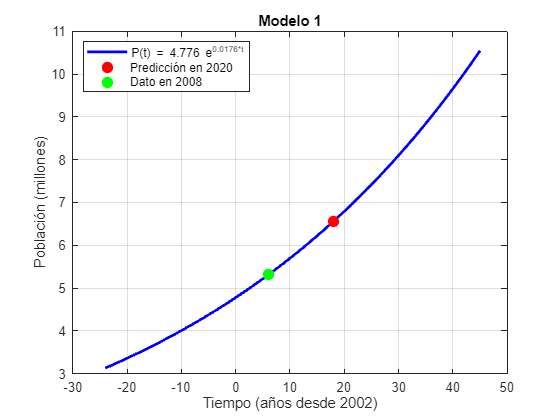


%------------------- GRAFICAR FUNCIÓN POBLACIONAL --------------------------
t = linspace(-24, 45, 100); % Valores de tiempo entre 0 y 50 años
P_t = P1(t); % Evaluar la función P(t) en los valores de t

figure; 
plot(t, P_t, 'b', 'LineWidth', 2); % Graficar P(t)
hold on; 
grid on

% Marcar puntos específicos
plot(18, P1_18, 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 8); % Predicción en 2020
plot(t1, P_t1, 'go', 'MarkerFaceColor', 'g', 'MarkerSize', 8); % Punto conocido en 2008

% Etiquetas y título
xlabel('Tiempo (años desde 2002)');
ylabel('Población (millones)');
title('Modelo 1');
legend('P(t) = 4.776 e^{0.0176*t}', 'Predicción en 2020', 'Dato en 2008', 'Location', 'NorthWest');

hold off;

- `MODELO #2`

primer modelo (1996-2008) 

población inicial de 2002 p(0)= 4.274

población de 2008 p(12)= 5.308


$$c=p\left(0\right)=4\ldotp 274$$



$$k=\frac{\ln \left(\frac{5\ldotp 308}{4\ldotp 274}\right)}{12}$$

$$\Rightarrow k=0\ldotp 018$$


Función #2


$$p\left(t\right)={4\ldotp 274*e}^{0\ldotp 018*t}$$


Evaluamos la funcion P(18)


$$P\left(24\right)=4\ldotp 274*e^{0\ldotp 018*24} \Rightarrow p\left(24\right)=6\ldotp 583$$


Porcentaje error

%$\textrm{Error}=\frac{|6\ldotp 196-6\ldotp 583|}{6\ldotp 196}*100\Rightarrow %\textrm{Error}=\;6\ldotp 245%$

%--------------------SEGUNDO MODELO------------------------
%Definición del modelo (1996-2008)
C2=4.274;
t2=12;
P_t2=5.308;
%Calcular k
k2=log(P_t2/C2)/t2;
%Definir la función P(t)
P2=@(t)C2*exp(k2*t);
%Calcular P(24) y error porcentual
P_real = 6.196;
P2_24=P2(24);
error2=abs((P_real-P2_24)/P_real)*100;


%Resultados
fprintf('Segundo modelo (1996-2008):\n');

Segundo modelo (1996-2008):


fprintf('C = %.4f\n', C2);

C = 4.2740


fprintf('k = %.4f\n', k2);

k = 0.0181


% Mostrar la función poblacional en la consola
fprintf('La función poblacional es: P(t) = %.3f * exp(%.4f * t)\n', C2, k2);

La función poblacional es: P(t) = 4.274 * exp(0.0181 * t)



fprintf('Evaluamos la funcion en el 2020 con un transcurso de 24 años:\n');

Evaluamos la funcion en el 2020 con un transcurso de 24 años:


fprintf('P(24) = %.3f\n', P2_24);

P(24) = 6.592


fprintf('Error porcentual = %.2f%%\n\n', error2);

Error porcentual = 6.39%



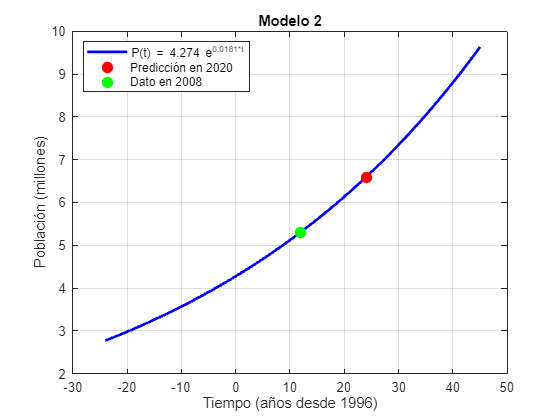


%------------------- GRAFICAR FUNCIÓN POBLACIONAL --------------------------
t_2 = linspace(-24, 45, 100); % Valores de tiempo entre 0 y 50 años
Pt2 = P2(t_2); % Evaluar la función P(t) en los valores de t

figure; 
plot(t_2, Pt2, 'b', 'LineWidth', 2); % Graficar P(t)
hold on; 
grid on


% Marcar puntos específicos
plot(24, P2_24, 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 8); % Predicción en 2020
plot(t2, P_t2, 'go', 'MarkerFaceColor', 'g', 'MarkerSize', 8); % Punto conocido en 2008

% Etiquetas y título
xlabel('Tiempo (años desde 1996)');
ylabel('Población (millones)');
title('Modelo 2');
legend('P(t) = 4.274 e^{0.0181*t}', 'Predicción en 2020', 'Dato en 2008', 'Location', 'NorthWest');

hold off;

- ***Modelo # 3***

Tercer Modelo (1988-1992)

Poblacion inial de 1988 $P\left(0\right)=3\ldotp 615$

Poblacion de 1992 $P\left(4\right)=3\ldotp 975$


$$C=P\left(0\right)=3\ldotp 615$$



$$k=\frac{\ln \left(\frac{3\ldotp 975}{3\ldotp 615}\right)}{4}\Longrightarrow k=0\ldotp 0237$$


Funcion # 3


$$P\left(t\right)=3\ldotp 615*e^{0\ldotp 0237*t}$$


Evaluamos la función P(32)


$$P\left(32\right)=3\ldotp 615*e^{0\ldotp 0237*32} \Longrightarrow P\left(32\right)=7\ldotp 717\;\textrm{millones}$$


Porcentaje de Error 


$$%\textrm{Errror}=\frac{\left|6\ldotp 196-7\ldotp 717\right|}{6\ldotp 196}*100\Longrightarrow %\textrm{Error}=\;24\ldotp 5%$$


%--------------------TERCER MODELO------------------------
%Definición del modelo (1988-1992)
C3=3.615;
t3=4;
P_t3=3.975;
%Calcular k
k3=log(P_t3/C3)/t3;
%Definir la función P(t)
P3=@(t)C3*exp(k3*t);
%Calcular P(32) y error porcentual
P_real = 6.196;
P3_32=P3(32);
error3=abs((P_real-P3_32)/P_real)*100;

%Resultados
fprintf('Tercer Modelo (1988-1992):\n');

Tercer Modelo (1988-1992):


fprintf('C = %.4f\n', C3);

C = 3.6150


fprintf('k = %.4f\n', k3);

k = 0.0237


% Mostrar la función poblacional en la consola
fprintf('La función poblacional es: P(t) = %.3f * exp(%.4f * t)\n', C3, k3);

La función poblacional es: P(t) = 3.615 * exp(0.0237 * t)



fprintf('Evaluamos la funcion en el 2020 con un transcurso de 32 años:\n');

Evaluamos la funcion en el 2020 con un transcurso de 32 años:


fprintf('P(32) = %.3f\n', P3_32);

P(32) = 7.726


fprintf('Error porcentual = %.2f%%\n\n', error3);

Error porcentual = 24.69%



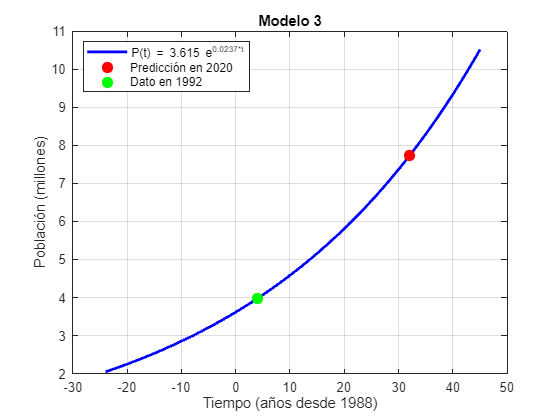




%------------------- GRAFICAR FUNCIÓN POBLACIONAL --------------------------
t_3 = linspace(-24, 45, 100); % Valores de tiempo entre 0 y 50 años
Pt3 = P3(t_3); % Evaluar la función P(t) en los valores de t

figure; 
plot(t_3, Pt3, 'b', 'LineWidth', 2); % Graficar P(t)
hold on; 
grid on

% Marcar puntos específicos
plot(32, P3_32, 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 8); % Predicción en 2020
plot(t3, P_t3, 'go', 'MarkerFaceColor', 'g', 'MarkerSize', 8); % Punto conocido en 1992

% Etiquetas y título
xlabel('Tiempo (años desde 1988)');
ylabel('Población (millones)');
title('Modelo 3');
legend('P(t) = 3.615 e^{0.0237*t}', 'Predicción en 2020', 'Dato en 1992', 'Location', 'NorthWest');

hold off;

- ***Modelo # 4***

Cuarto Modelo (1984-2012)

Poblacion inial de 1984 $P\left(0\right)=3\ldotp 279$

Poblacion del 2012 $P\left(28\right)=5\ldotp 66$


$$C=P\left(0\right)=3\ldotp 279$$



$$k=\frac{\ln \left(\frac{5\ldotp 66}{3\ldotp 279}\right)}{28}\Longrightarrow k=0\ldotp 019$$


Funcion # 4


$$P\left(t\right)=3\ldotp 279*e^{0\ldotp 019*t}$$


Evaluamos la función en P(32)


$$P\left(36\right)=3\ldotp 279*e^{0\ldotp 019*36} \Longrightarrow P\left(36\right)=6\ldotp 498$$


Porcentaje de Error 


$$%\textrm{Errror}=\frac{\left|6\ldotp 196-6\ldotp 498\right|}{6\ldotp 196}*100\Longrightarrow \;%\textrm{Error}=\;4\ldotp 874%$$


%--------------------CUARTO MODELO------------------------
%Definición del modelo (1984-2012)
C4=3.279;
t4=28;
P_t4=5.66;
%Calcular k
k4=round((log(P_t4/C4)/t4),3);
%Definir la función P(t)
P4=@(t)C4*exp(k4*t);
%Calcular P(36) y error porcentual
P_real = 6.196;
P4_36=P4(36);
error4=abs((P_real-P4_36)/P_real)*100;

%Resultados
fprintf('Cuarto Modelo (1984-2012):\n');

Cuarto Modelo (1984-2012):


fprintf('C = %.4f\n', C4);

C = 3.2790


fprintf('k = %.4f\n', k4);

k = 0.0190


% Mostrar la función poblacional en la consola
fprintf('La función poblacional es: P(t) = %.3f * exp(%.4f * t)\n', C4, k4);

La función poblacional es: P(t) = 3.279 * exp(0.0190 * t)



fprintf('Evaluamos la funcion en el 2020 con un transcurso de 36 años:\n');

Evaluamos la funcion en el 2020 con un transcurso de 36 años:


fprintf('P(36) = %.3f\n', P4_36);

P(36) = 6.498


fprintf('Error porcentual = %.2f%%\n\n', error4);

Error porcentual = 4.88%



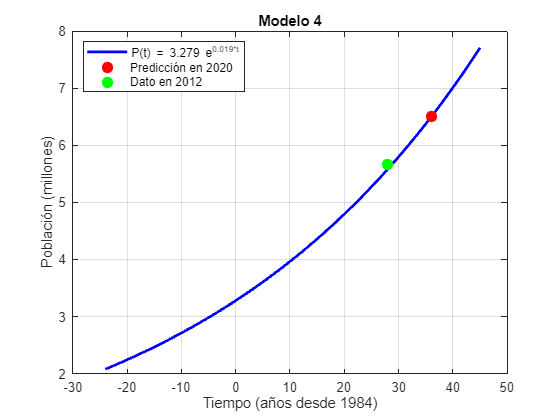



%------------------- GRAFICAR FUNCIÓN POBLACIONAL --------------------------
t_4 = linspace(-24, 45, 100); % Valores de tiempo entre 0 y 50 años
Pt4 = P4(t_4); % Evaluar la función P(t) en los valores de t

figure; 
plot(t_4, Pt4, 'b', 'LineWidth', 2); % Graficar P(t)
hold on; 
grid on

% Marcar puntos específicos
plot(36, P4_36, 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 8); % Predicción en 2020
plot(t4, P_t4, 'go', 'MarkerFaceColor', 'g', 'MarkerSize', 8); % Punto conocido en 2012

% Etiquetas y título
xlabel('Tiempo (años desde 1984)');
ylabel('Población (millones)');
title('Modelo 4');
legend('P(t) = 3.279 e^{0.019*t}', 'Predicción en 2020', 'Dato en 2012', 'Location', 'NorthWest');

hold off;

- ***Modelo # 5***

Cuarto Modelo (1982-1992)

Poblacion inial de 1982 $P\left(0\right)=3\ldotp 132$

Poblacion de 1992 $P\left(10\right)=3\ldotp 972$


$$C=P\left(0\right)=3\ldotp 132$$



$$k=\frac{\ln \left(\frac{3\ldotp 972}{3\ldotp 132}\right)}{10}\Longrightarrow k=0\ldotp 023$$


Funcion # 5


$$P\left(t\right)=3\ldotp 132*e^{0\ldotp 023*t}$$


Evaluamos la función en P(38)


$$P\left(38\right)=3\ldotp 132*e^{0\ldotp 023*38} \Longrightarrow P\left(38\right)=7\ldotp 505$$


Porcentaje de Error 


$$%\textrm{Errror}=\frac{\left|6\ldotp 196-7\ldotp 505\right|}{6\ldotp 196}*100\Longrightarrow %\textrm{Error}=21\ldotp 12%$$


%--------------------QUINTO MODELO------------------------
%Definición del modelo (1982-1992)
C5=3.132;
t5=10;
P_t5=3.972;
%Calcular k
k5=round((log(P_t5/C5)/t5),4);
%Definir la función P(t)
P5=@(t)C5*exp(k5*t);
%Calcular P(38) y error porcentual
P_real = 6.196;
P5_38=P5(38);
error5=abs((P_real-P5_38)/P_real)*100;

%Resultados
fprintf('Quinto Modelo (1982-1992):\n');

Quinto Modelo (1982-1992):


fprintf('C = %.4f\n', C5);

C = 3.1320


fprintf('k = %.4f\n', k5);

k = 0.0238


% Mostrar la función poblacional en la consola
fprintf('La función poblacional es: P(t) = %.3f * exp(%.4f * t)\n', C5, k5);

La función poblacional es: P(t) = 3.132 * exp(0.0238 * t)



fprintf('Evaluamos la funcion en el 2020 con un transcurso de 38 años:\n');

Evaluamos la funcion en el 2020 con un transcurso de 38 años:


fprintf('P(38) = %.3f\n', P5_38);

P(38) = 7.737


fprintf('Error porcentual = %.2f%%\n\n', error5);

Error porcentual = 24.88%



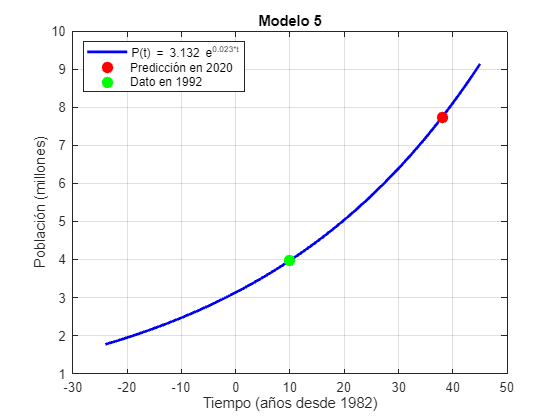



%------------------- GRAFICAR FUNCIÓN POBLACIONAL --------------------------
t_5 = linspace(-24, 45, 100); % Valores de tiempo entre 0 y 50 años
Pt5 = P5(t_5); % Evaluar la función P(t) en los valores de t

figure; 
plot(t_5, Pt5, 'b', 'LineWidth', 2); % Graficar P(t)
hold on; 
grid on

% Marcar puntos específicos
plot(38, P5_38, 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 8); % Predicción en 2020
plot(t5, P_t5, 'go', 'MarkerFaceColor', 'g', 'MarkerSize', 8); % Punto conocido en 1992

% Etiquetas y título
xlabel('Tiempo (años desde 1982)');
ylabel('Población (millones)');
title('Modelo 5');
legend('P(t) = 3.132 e^{0.023*t}', 'Predicción en 2020', 'Dato en 1992', 'Location', 'NorthWest');

hold off;

## Grafica de la recta tangente hechas en excel.

Teniendo en cuenta la base de datos se extrae una pequeña muestra donde se le hallara el ajuste exponencial y la rectatangente en Excel. Sin embargo,  para confirmar la viabilidad de los datos que sean precisos se realiza el codigo, logrando graficar estas expresiones y comparando con el archivo Excel.

% Definir el vector de tiempo de 0 a 40 años
t = (0:40)';

% Datos de población (columna B de la hoja 'Muestra')
Poblacion = [
    2905750; 2956410; 3008030; 3061720; 3132660; 3205230; 3279590; 3355460;
    3433950; 3523630; 3615780; 3710070; 3806960; 3904150; 3975530; 4048000;
    4121910; 4197160; 4274260; 4355040; 4437460; 4521450; 4607140; 4693500;
    4776700; 4861370; 4947660; 5035230; 5124530; 5215740; 5308710; 5403060;
    5499230; 5592610; 5660140; 5728300; 5797380; 5867290; 5938140; 6009850;
    6082420
];

% Calcular la función F1 = 3,000,000 * e^(0.019t)
F1 = 3000000 * exp(0.019 * t);

% Calcular la derivada F1' = 57,000 * e^(0.019t)
F1_Derivada = 57000 * exp(0.019 * t);

% Calcular la recta tangente en t=0: F1(0) + F1'(0)*t
Recta_tangente = 3000000 + 57000 * t;

% Crear la tabla
tabla = table(t, Poblacion, F1, F1_Derivada, Recta_tangente, ...
    'VariableNames', {'Tiempo', 'Poblacion', 'F1', 'F1_Derivada', 'Recta_tangente'});

% Configurar MATLAB para mostrar todas las filas
format long;  % Precisión numérica
set(0, 'DefaultFigureWindowStyle', 'docked');  % Evitar truncado en ventana

% Mostrar la tabla completa (0-40)
disp('Tabla completa Muestra (t=0 a t=40):');

Tabla completa Muestra (t=0 a t=40):


disp(tabla);

    Tiempo    Poblacion           F1             F1_Derivada       Recta_tangente
    ______    _________    ________________    ________________    ______________

       0       2905750              3000000               57000       3000000    
       1       2956410     3057544.94585222    58093.3539711922       3057000    
       2       3008030     3116193.69863549    59207.6802740744       3114000    
       3       3061720      3175967.4311865    60343.3811925435       3171000    
       4       3132660     3236887.72247185    61500.8667269652       3228000    
       5       3205230     3298976.56537831    62680.5547421879       3285000    
       6       3279590     3362256.37465246    63882.8711183967       3342000    
       7       3355460     3426749.99499268     65108.249904861       3399000    
       8 


% Corroborar resultados para t=0 y t=40
fprintf('\nVerificación para t=0:\n');


Verificación para t=0:


fprintf('F1(0) calculado: %.2f\n', F1(1));

F1(0) calculado: 3000000.00


fprintf('F1_Derivada(0) calculado: %.2f\n', F1_Derivada(1));

F1_Derivada(0) calculado: 57000.00


fprintf('Recta tangente(0) calculada: %.2f\n\n', Recta_tangente(1));

Recta tangente(0) calculada: 3000000.00




fprintf('Verificación para t=40:\n');

Verificación para t=40:


fprintf('F1(40) calculado: %.2f\n', F1(end));

F1(40) calculado: 6414828.66


fprintf('F1_Derivada(40) calculado: %.2f\n', F1_Derivada(end));

F1_Derivada(40) calculado: 121881.74


fprintf('Recta tangente(40) calculada: %.2f\n', Recta_tangente(end));

Recta tangente(40) calculada: 5280000.00


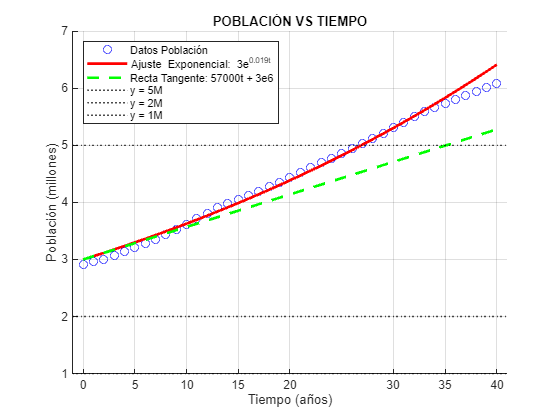


% Graficar los datos y modelos
figure;
hold on;

% 1. Datos de población (puntos azules)
plot(t, Poblacion/1e6, 'bo', 'MarkerSize', 6, 'DisplayName', 'Datos Población');

% 2. Ajuste exponencial (línea roja continua)
plot(t, F1/1e6, 'r-', 'LineWidth', 2, 'DisplayName', 'Ajuste Exponencial: 3e^{0.019t}');

% 3. Recta tangente (línea verde discontinua)
plot(t, Recta_tangente/1e6, 'g--', 'LineWidth', 2, 'DisplayName', 'Recta Tangente: 57000t + 3e6');

% 4. Líneas horizontales de referencia
yline(5, 'k:', 'LineWidth', 1, 'DisplayName', 'y = 5M');
yline(2, 'k:', 'LineWidth', 1, 'DisplayName', 'y = 2M');
yline(1, 'k:', 'LineWidth', 1, 'DisplayName', 'y = 1M');

% Configuración del gráfico
title('POBLACIÓN VS TIEMPO', 'FontSize', 12, 'FontWeight', 'bold');
xlabel('Tiempo (años)', 'FontSize', 10);
ylabel('Población (millones)', 'FontSize', 10);
grid on;

% Ajustar límites y marcas del eje X
xlim([-1 41]);  % Extender ligeramente más allá de t=40
xticks([0 5 10 15 20 30 35 40]);  % Marcas especificadas en la imagen
set(gca, 'FontSize', 9);

% Leyenda y posición
legend('Location', 'northwest', 'FontSize', 8);
hold off;


% Mostrar tabla completa (opcional)
disp(tabla);

    Tiempo    Poblacion           F1             F1_Derivada       Recta_tangente
    ______    _________    ________________    ________________    ______________

       0       2905750              3000000               57000       3000000    
       1       2956410     3057544.94585222    58093.3539711922       3057000    
       2       3008030     3116193.69863549    59207.6802740744       3114000    
       3       3061720      3175967.4311865    60343.3811925435       3171000    
       4       3132660     3236887.72247185    61500.8667269652       3228000    
       5       3205230     3298976.56537831    62680.5547421879       3285000    
       6       3279590     3362256.37465246    63882.8711183967       3342000    
       7       3355460     3426749.99499268     65108.249904861       3399000    
       8 

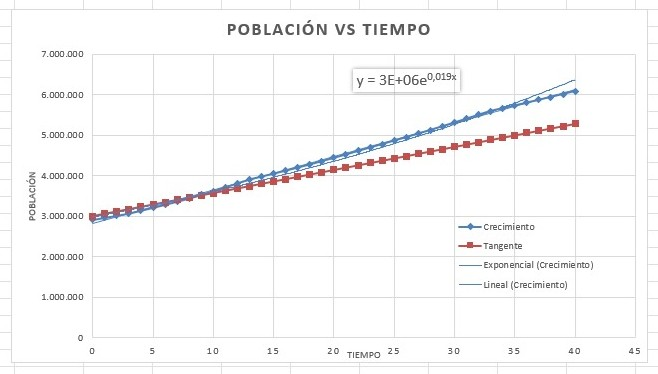

## Entrega Segundo Corte.

## Introducción. 

Para la segunda parte del proyecto se utilizo la ecuación logística, la cual nos ayuda a entender cómo crecen las poblaciones en la vida real, considerando que no pueden crecer siempre, por factores externos, además tiene una variación de la ecuación diferencial poblacional que incluye un nuevo término:


$$\frac{\textrm{dP}}{\textrm{dt}}=r\;P\;\left(1-\frac{P}{K}\right)$$


Se debe tener en cuenta cuando:

- $K<P$ Creciente

- $K>P$  Decreciente

- $K=P$ Constante

En la ecuación, **r** representa la tasa de crecimiento y **K** la capacidad de soporte, es decir, el punto en el que la población se estabiliza por factores influyentes como recursos ilimitados o restrincciones externos.

El obejtivo propuesto es resolver la ecuación diferencial y usar los valores iniciales obtenidos en el primer corte para construir dos soluciones explícitas. El valor de **K** puede ser elegido libremente, basado en una estimación razonable de la población máxima esperada.

Luego, se debe calcular la población actual según las soluciones anteriores y ajustar el valor de **r** , el cual debe tener un error menor del 10% con respecto a los datos actuales.

## Solución de la ecuación.


$$\frac{\textrm{dP}}{\textrm{dt}}\;=\;r\;P\;\left(1-\frac{P}{K}\right)$$
 
$$\Rightarrow \;\frac{\textrm{dP}}{\textrm{dt}}\;=\;P\left(r-\frac{\textrm{rP}}{k}\right)\Rightarrow \;\frac{\textrm{dP}}{\textrm{dt}}=\;P\left(a-\textrm{bP}\right)$$


- r = Tasa de crecimiento

- k = Constante de sostenimiento  


$$a=r$$



$$b=\frac{r}{k}$$



$$\frac{\textrm{dP}}{\textrm{dt}}\;=\;P\left(a-\textrm{bP}\right)\;\Rightarrow \int \frac{\textrm{dP}}{P\left(a-\textrm{bP}\right)}\;=\int \textrm{dt}$$
 


$$\frac{1}{P\left(a-\textrm{bP}\right)}\;=\;\frac{A}{P}\;+\;\frac{B}{a-\textrm{bP}}$$



$$1\;=\;A\left(a-\textrm{bP}\right)+\textrm{BP}\;\Rightarrow \;$$

$$\begin{array}{l}
\lbrace \textrm{Si}\;P\;=\;0\;\Rightarrow 1=\textrm{Aa}\rbrace \\
\lbrace \textrm{Si}\;P\;=\;1\;\Rightarrow 0=-\textrm{Aa}+B\rbrace 
\end{array}$$
 


$$0\;=\;\frac{1}{a}\;b+B\;\Rightarrow B\;=\;\frac{b}{a}$$



$$\int \left(\frac{\frac{1}{a}}{P}\;+\;\frac{\frac{b}{a}}{a-\textrm{bP}}\right)\textrm{dP}\;=\int \textrm{dt}\;\Rightarrow \;\;\frac{1}{a}\;\ln \left|P\right|\;-\;\frac{1}{a}\;\ln \left|a-\textrm{bP}\right|=t+c$$



$$\ln \left|P\right|-\ln \left|a-\textrm{bP}\right|\;=\;\textrm{at}+\textrm{ac}\;\Rightarrow \;\ln \left|\frac{P}{a-\textrm{bP}}\right|\;=\;\textrm{at}+\textrm{ac}$$
 


$$\frac{P}{a-\textrm{bP}}\;=\;e^{\textrm{at}+\textrm{ac}} \;\Rightarrow P=\;\textrm{ac}e^{\textrm{at}} -\textrm{bPc}e^{\textrm{at}}$$
   


$$P+\textrm{Pbc}e^{\textrm{at}} \;=\;\textrm{ac}e^{\textrm{at}} \;\Rightarrow P\left(1+\textrm{bc}e^{\textrm{at}} \right)\;=\textrm{ac}e^{\textrm{at}}$$



$$P\left(t\right)\;=\;\frac{\textrm{ac}e^{\textrm{at}} }{1+\textrm{bc}e^{\textrm{at}} }\;\;\Rightarrow \;\;\mathit{\mathbf{P}}\left(\mathit{\mathbf{t}}\right)\;=\;\frac{\textrm{ac}}{{\mathit{\mathbf{e}}}^{-\textrm{at}} +\textrm{bc}}$$


## Valores iniciales:

- 
$$P\left(0\right)=P_o$$


- 
$$P\left(t\right)=P_1$$


- 
$$\textrm{Pmax}=x$$


- 
$$a=x*k$$



$$P_o \;=\;\frac{\textrm{xkc}}{e^{-r\left(0\right)} +\textrm{kc}}\;\;\;\Rightarrow \;\;\;$$

$$P_o \;=\;\frac{\textrm{xkc}}{1+\textrm{kc}}$$
  


$$1+\textrm{kc}\;=\;\frac{\textrm{xkc}}{P_o }$$
 


$$1\;=\;\frac{x}{P_o }\;\textrm{kc}-\textrm{kc}$$



$$1=\textrm{kc}\left(\frac{x}{p_o }-1\right)$$



$$\textrm{kc}\;=\;\frac{1}{\frac{x}{P_o }-1}\;=\;\frac{\frac{1}{1}}{\frac{x-P_o }{P_o }}$$



$$\textrm{kc}=\frac{{\mathit{\mathbf{P}}}_{\mathit{\mathbf{o}}} }{\mathit{\mathbf{x}}-{\mathit{\mathbf{P}}}_{\mathit{\mathbf{o}}} }$$


## Hallar constante de crecimiento r:


$$P\left(t_1 \right)=P_1$$



$$P_1 \;=\;\frac{\frac{xP_o }{x-P_o }}{e^{-xt_1 k} +\frac{P_o }{x-P_o }}$$



$$e^{-xt_1 k} +\frac{P_o }{x-P_o }\;=\;\frac{\frac{xP_o }{x-P_o }}{P_1 }$$



$$e^{-xt_1 k} =\;\frac{\frac{xP_o }{x-P_o }}{P_1 }\;-\;\frac{P_o }{x-P_o }$$



$$\ln \;e^{-xt_1 k} \;=\;\ln \left|\frac{xP_o }{P_1 \left(x-P_o \right)}\;-\;\frac{P_o }{x-P_o }\right|$$



$$\frac{\ln \left|\frac{\textrm{Pmax}P_o -P_o P_1 }{P_1 \left(\textrm{Pmax}-P_o \right)}\right|}{-\textrm{Pmax}{*t}_1 }$$


#### **Primera ecuación:   Modelo 1984 - 1985  **


$$P\left(0\right)=3\ldotp 279$$



$$P\left(1\right)=3\ldotp 355$$



$$\textrm{Pmax}=8\ldotp 5$$


Teniendo en cuenta estos valores, se reeemplaza en las ecuaciones anteriores hallamos kc:

- 
$$\textrm{kc}=\frac{{\mathit{\mathbf{P}}}_{\mathit{\mathbf{o}}} }{\textrm{Pmax}-{\mathit{\mathbf{P}}}_{\mathit{\mathbf{o}}} }\longrightarrow \textrm{kc}=\frac{3\ldotp 279}{8\ldotp 5-3\ldotp 279\;\;}\longrightarrow \textrm{kc}=0\ldotp 628$$
 

- 
$$k\;=\frac{\ln \left|\frac{\textrm{Pmax}P_o -P_o P_1 }{P_1 \left(\textrm{Pmax}-P_o \right)}\right|}{-\textrm{Pmax}*t_1 }\longrightarrow k\;=\frac{\ln \left|\frac{8\ldotp 5\;*3\ldotp 279-3\ldotp 279*3\ldotp 355}{3\ldotp 355\left(8\ldotp 5-3\ldotp 279\right)}\right|}{-8\ldotp 5\left(1\right)}\longrightarrow k=0\ldotp 00442$$


- $r=k*\textrm{Pmax}\longrightarrow r=0\ldotp 00442*8\ldotp 5\longrightarrow r=0\ldotp 03757$ Constante de Crecimiento

- 
$$P\left(t\right)=\frac{5\ldotp 338}{e^{-0\ldotp 03757*t} +0\ldotp 628}$$
 

En la ecuacion de población anterior se busca predecir la población en el año 2020, teniendo presente desde el año inicial hasta el 2020 donde pasaron 36 años:


$$P\left(t\right)=\frac{5\ldotp 338}{e^{-0\ldotp 03757*36} +0\ldotp 628}\longrightarrow P\left(t\right)=6\ldotp 02$$
 

La población en el año 2020 sera 6.02. Se desea hallar el porcentaje de error del dato calculado con el dato real, donde este sera valor sera 6.196. Se reemplaza estos valores en la siguiente ecuación:


$$%\;\textrm{error}=\left|\frac{\textrm{Valor}\;\textrm{real}-\textrm{valor}\;\;\textrm{calculado}}{\textrm{valor}\;\textrm{real}}\right|*100%\;$$



$$%\;\textrm{error}=\left|\frac{6\ldotp 196-6\ldotp 02}{6\ldotp 196}\right|*100%\;$$



$$%\;\textrm{error}=2\ldotp 84%$$


### Codigo

%% MODELO EXPONENCIAL (CUARTO MODELO - 1984 a 1985)
% Datos iniciales
C4 = 3.279;        % P(0)
t4 = 1;           % Tiempo en años para P(1)
P_t4 = 3.355;       % P(1)

% Calcular la tasa k4 a partir de P(1)=C4*exp(k4*t4)
k4 = round(log(P_t4/C4)/t4, 3);

% Definir la función exponencial
P4 = @(t) C4 * exp(k4*t);

% Dominios para evaluar el modelo exponencial
t_expo = linspace(0, 60, 100); % de 0 a 50 años (desde 1984)
Pt4 = P4(t_expo);
P4_36 = P4(36);  % Predicción para t = 36 (año 2020, considerando 1984 como t=0)

%% MODELO LOGÍSTICO
% Parámetros obtenidos en el proceso de separación de variables:
% Se tiene la solución en la forma: P(t)=5.338/(exp(-0.0412*t)+0.628)
k_cap = 8.5;     % Capacidad de carga (no se usa directamente en la fórmula final)
A = 0.628;       % Constante determinada a partir de P(0)=3.279
r = 0.03757;      % Tasa de crecimiento
num = 5.338;     % Producto de 8.5*A

% Definir la función logística
P_log = @(t) num ./ (exp(-r*t) + A);

% Dominios para evaluar el modelo logístico
t_log = linspace(0, 60, 100);
P_log_values = P_log(t_log);
P_log_36 = P_log(36);  % Valor para t = 36 (2020)

%% GRAFICAR AMBOS MODELOS EN UN SOLO GRÁFICO
figure;
hold on;
% Graficar modelo exponencial
plot(t_expo, Pt4, 'b-', 'LineWidth', 2);
% Graficar modelo logístico
plot(t_log, P_log_values, 'r', 'LineWidth', 2);

% Marcar puntos de interés
plot(36, P4_36, 'bo', 'MarkerFaceColor', 'b', 'MarkerSize', 8);   % Predicción 2020 (modelo exponencial)
plot(36, P_log_36, 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 8);   % Predicción 2020 (modelo logístico)

% Etiquetas y leyenda
xlabel('Tiempo (años desde 1984)');
ylabel('Población (millones)');
title('Comparación de Modelos: Exponencial vs. Logístico');
legend('Modelo Exponencial: P(t)=3.279 e^{k t}', 'Modelo Logístico: P(t)=5.338/(e^{-0.03757t}+0.628)', ...
    'Predicción 2020 (Exponencial)',  'Predicción 2020 (Logístico)', ...
    'Location', 'NorthWest');
grid on;
hold off;

%% RESULTADOS EN CONSOLA
fprintf('Modelo Exponencial (1984-1985):\n');

Modelo Exponencial (1984-1985):


fprintf('C = %.4f\n', C4);

C = 3.2790


fprintf('k = %.4f\n', k4);

k = 0.0230


fprintf('La función poblacional es: P(t) = %.3f * exp(%.4f*t)\n', C4, k4);

La función poblacional es: P(t) = 3.279 * exp(0.0230*t)


fprintf('P(36) = %.3f\n\n', P4_36);

P(36) = 7.505




fprintf('Modelo Logístico:\n');

Modelo Logístico:


fprintf('La función poblacional es: P(t)=5.338/(e^{-0.03757*t}+0.628)\n');

La función poblacional es: P(t)=5.338/(e^{-0.03757*t}+0.628)


fprintf('P(36) = %.3f\n', P_log_36);

P(36) = 6.021


**Segunda Ecuación: Modelo  2000 - 2001**


$$P\left(0\right)=4\ldotp 607$$



$$P\left(1\right)=4\ldotp 693$$



$$\textrm{Pmax}=8$$


Teniendo en cuenta estos valores, se reeemplaza en las ecuaciones anteriores hallamos kc:

- 
$$\textrm{kc}=\frac{{\mathit{\mathbf{P}}}_{\mathit{\mathbf{o}}} }{\textrm{Pmax}-{\mathit{\mathbf{P}}}_{\mathit{\mathbf{o}}} }\longrightarrow \textrm{kc}=\frac{4\ldotp 607}{8-4\ldotp 607}\longrightarrow \textrm{kc}=1\ldotp 357$$


- 
$$k\;=\frac{\ln \left|\frac{\textrm{Pmax}P_o -P_o P_1 }{P_1 \left(\textrm{Pmax}-P_o \right)}\right|}{-\textrm{Pmax}*t_1 }\longrightarrow k\;=\frac{\ln \left|\frac{8*4\ldotp 607-4\ldotp 607*4\ldotp 693}{4\ldotp 693\left(8-4\ldotp 607\right)}\right|}{-8\left(1\right)}\longrightarrow k=0\ldotp 005521$$


- $r=k*\textrm{Pmax}\longrightarrow r=0\ldotp 005521*8\longrightarrow r=0\ldotp 0441$ Constante de Crecimiento 

- 
$$P\left(t\right)=\frac{10\ldotp 856}{e^{-0\ldotp 0441*t} +1\ldotp 357}$$
 

En la ecuacion de población anterior se busca predecir la población en el año 2020, teniendo presente desde el año inicial hasta el 2020 donde pasaron 20 años:

- 
$$P\left(36\right)=\frac{10\ldotp 856}{e^{-0\ldotp 0441*20} +1\ldotp 357}=6\ldotp 13$$
  

Hallamos el porcentaje de error 

- 
$$%\;\textrm{error}=\left|\frac{6\ldotp 196-6\ldotp 13}{6\ldotp 196}\right|*100%\;=1\ldotp 07%$$


%% MODELO EXPONENCIAL (CUARTO MODELO - 2000 a 2001)
% Datos iniciales
C4 = 4.607;        % P(0)
t4 = 1;           % Tiempo en años para P(1)
P_t4 = 4.693;       % P(1)

% Calcular la tasa k4 a partir de P(1)=C4*exp(k4*t4)
k4 = round(log(P_t4/C4)/t4, 3);

% Definir la función exponencial
P4 = @(t) C4 * exp(k4*t);

% Dominios para evaluar el modelo exponencial
t_expo = linspace(0, 100, 100); % de 0 a 50 años (desde 2000)
Pt4 = P4(t_expo);
P4_20 = P4(20);  % Predicción para t = 20 (año 2020, considerando 2000 como t=0)

%% MODELO LOGÍSTICO
k_cap = 8;     % Capacidad de carga (no se usa directamente en la fórmula final)
A = 1.357;       % Constante determinada a partir de P(0)=3.279
r = 0.0441;      % Tasa de crecimiento
num = 10.856;     % Producto de 8*A

% Definir la función logística
P_log = @(t) num ./ (exp(-r*t) + A);

% Dominios para evaluar el modelo logístico
t_log = linspace(0, 100, 100);
P_log_values = P_log(t_log);
P_log_20 = P_log(20);  % Valor para t = 20 (2020)

%% GRAFICAR AMBOS MODELOS EN UN SOLO GRÁFICO
figure;
hold on;
% Graficar modelo exponencial
plot(t_expo, Pt4, 'b-', 'LineWidth', 2);
% Graficar modelo logístico
plot(t_log, P_log_values, 'r', 'LineWidth', 2);

% Marcar puntos de interés
plot(20, P4_20, 'bo', 'MarkerFaceColor', 'b', 'MarkerSize', 8);   % Predicción 2020 (modelo exponencial)
plot(20, P_log_20, 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 8);   % Predicción 2020 (modelo logístico)

% Etiquetas y leyenda
xlabel('Tiempo (años desde 2000)');
ylabel('Población (millones)');
title('Comparación de Modelos: Exponencial vs. Logístico');
legend('Modelo Exponencial: P(t)=3.279 e^{k t}', 'Modelo Logístico: P(t)=10.856/(e^{-0.0441t}+1.357)', ...
    'Predicción 2020 (Exponencial)',  'Predicción 2020 (Logístico)', ...
    'Location', 'NorthWest');
grid on;
hold off;

%% RESULTADOS EN CONSOLA
fprintf('Modelo Exponencial (2000-2001):\n');

Modelo Exponencial (2000-2001):


fprintf('C = %.4f\n', C4);

C = 4.6070


fprintf('k = %.4f\n', k4);

k = 0.0180


fprintf('La función poblacional es: P(t) = %.3f * exp(%.4f*t)\n', C4, k4);

La función poblacional es: P(t) = 4.607 * exp(0.0180*t)


fprintf('P(20) = %.3f\n\n', P4_20);

P(20) = 6.603




fprintf('Modelo Logístico:\n');

Modelo Logístico:


fprintf('La función poblacional es: P(t)=10.856/(e^{-0.0441*t}+1.357)\n');

La función poblacional es: P(t)=10.856/(e^{-0.0441*t}+1.357)


fprintf('P(20) = %.3f\n', P_log_20);

P(20) = 6.130


**Conclusiones**

En este proyecto se usaron dos modelos para predecir la población en ciertos años: la ecuación poblacional y otra que es la ecuación logística. Al comparar los resultados, vimos que la ecuación logística dio errores porcentuales mucho más bajos, lo que muestra que es más precisa.

Esto se debe a que la ecuación logística no solo modela el crecimiento, sino que también considera que hay un límite en los recursos y el espacio, es decir, que la población no puede crecer para siempre. Ese límite, conocido como K, hace que el crecimiento se frene poco a poco a medida que se acerca a ese tope. Gracias a eso, el modelo se ajusta mejor a cómo funciona realmente el crecimiento poblacional.

En resumen, aunque los dos modelos sirven para hacer estimaciones, la ecuación logística es más realista y da resultados más cercanos a lo que realmente pasa, porque toma en cuenta los factores que afectan el crecimiento a largo plazo.

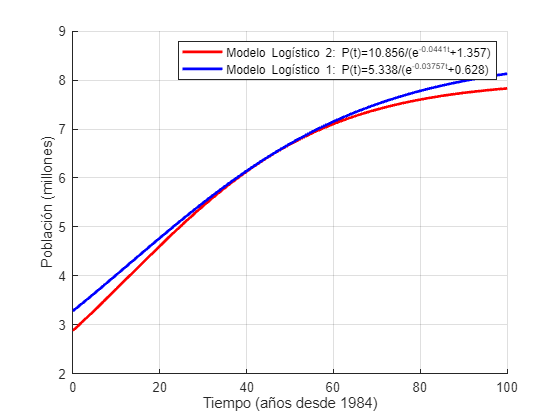

%% MODELO LOGÍSTICO 1
k_cap1 = 8.5;     % Capacidad de carga (no se usa directamente en la fórmula final)
A1 = 0.628;       % Constante determinada a partir de P(0)=3.279
r1 = 0.03557;      % Tasa de crecimiento
num1 = 5.338;     % Producto de 8.5*A

% Definir la función logística
P_log1 = @(t) num1 ./ (exp(-r1*t) + A1);


% Dominios para evaluar el modelo logístico
t_log1 = linspace(0, 100, 100);
P_log_values1 = P_log1(t_log1);
P_log = P_log1(36);  % Valor para t = 36 (2020)


%% MODELO LOGÍSTICO 2
k_cap = 8;     % Capacidad de carga (no se usa directamente en la fórmula final)
A = 1.357;       % Constante determinada a partir de P(0)=3.279
r = 0.0441;      % Tasa de crecimiento
num = 10.856;     % Producto de 8*A

% Definir la función logística
P_log = @(t) num ./ (exp(-r*(t-20)) + A);

% Dominios para evaluar el modelo logístico
t_log = linspace(0, 100, 100);
P_log_values = P_log(t_log);
P_log_20 = P_log(20);  % Valor para t = 20 (2020)

%% GRAFICAR AMBOS MODELOS EN UN SOLO GRÁFICO
figure;
hold on;
% Graficar modelo logístico 1 y 2
plot(t_log, P_log_values, 'r', 'LineWidth', 2);
plot(t_log1, P_log_values1, 'b', 'LineWidth', 2);

legend('Modelo Logístico 2: P(t)=10.856/(e^{-0.0441t}+1.357)', 'Modelo Logístico 1: P(t)=5.338/(e^{-0.03757t}+0.628)');

% Etiquetas y leyenda
xlabel('Tiempo (años desde 1984)');
ylabel('Población (millones)');
grid on;
hold off;

## Entrega Tercer Corte.

## Introducción. 

En esta tercera y última parte del proyecto, se empleó el método de la transformada de Laplace como herramienta principal para resolver la ecuación logística y poblacional que modela el crecimiento poblacional. Este tipo de ecuación diferencial describe cómo una población evoluciona en el tiempo bajo la influencia de factores limitantes. A través de la transformada de Laplace, es posible convertir la ecuación diferencial en una expresión algebraica más manejable, lo que facilita su análisis y solución. Este enfoque no solo permite obtener una solución exacta, sino también comprender mejor la dinámica del crecimiento poblacional en diferentes escenarios.

## Solucion de la ecuacion poblacional por metodo de la place.


$$\frac{\textrm{dp}}{\textrm{dt}}=\textrm{kp}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;p\left(o\right)=P_0$$



$$\frac{\textrm{dp}}{\textrm{dt}}\;-\;\textrm{kp}\;=0\;\;\;\Rightarrow \;\;L\left\lbrace \frac{\textrm{dp}}{\textrm{dt}}\right\rbrace -\textrm{kL}\;\left\lbrace p\right\rbrace =L\left\lbrace 0\right\rbrace$$



$$s\;p\left(s\right)\;-\;P_0 -\;k\;p\left(s\right)=0$$



$$p\left(s\right)\;\left(s-k\right)=P_0 \;\;\;\;\Rightarrow \;\;\;p\left(s\right)=\;\frac{P_0 }{\left(s-k\right)}$$



$$P\left(s\right)=L^{-1} \;\left\lbrace \frac{P_0 }{s-k}\right\rbrace \;\;\;\Rightarrow \;\;\;\;p\left(t\right)={\;P}_0 \;e^{k*t}$$
  

## Solucion de la ecuacion logistica por metodo de la place.

se debe tener en cuenta que: 

- 
$$a=r$$


- 
$$b=\frac{r}{k}$$



$$\frac{\textrm{dp}}{\textrm{dt}}=\textrm{rp}\left(1\;-\;\frac{p}{k}\right)\;\;\Rightarrow \;\;\frac{\textrm{dp}}{\textrm{dt}}=\textrm{ap}-bp^2$$



$$\frac{\textrm{dp}}{\textrm{dt}}-\textrm{ap}=-bp^2$$


Transformación de ecuación de segundo grado a lineal por metodo de bernoulli.


$$n=2\;\;\;\;\;\;\;\;u=p^{1-2} \;\;\;\;\;\Rightarrow \;\;\;\;\;u=p^{-1} \;$$



$$u^{-1} =p\;\;\;\;\;\;\;u^{-2} =p^2 \;{\;\;\;\;\;\;\;-u}^{-2\;} \frac{\textrm{du}}{\textrm{dt}}=\frac{\textrm{dp}}{\textrm{dt}}$$



$$\left(-u^{-2} \;\frac{\textrm{du}}{\textrm{dt}}-au^{-1} =-bu^{-2} \right)\div \left(u^{-2} \right)$$



$$u_{\left(0\right)} =u_0 =\frac{1}{P_0 }$$



$$\frac{\textrm{du}}{\textrm{dt}}+\textrm{au}=b\;\;\;\Rightarrow \;\;L\left\lbrace \frac{\textrm{du}}{\textrm{dt}}\right\rbrace +\textrm{aL}\left\lbrace u\right\rbrace =L\left\lbrace b\right\rbrace$$



$${\textrm{sU}}_{\left(s\right)} -u_{0\;} +{\textrm{aU}}_{\left(s\right)} =\frac{b}{s}$$



$$U_{\left(s\right)} \;\left(s+a\right)=\frac{b}{s}\;+\;u_{0\;\;} \;\Rightarrow \;U_{\left(s\right)\;} =\;\frac{\frac{b}{\;s}+\frac{u_0 }{1}}{s+a}$$



$$U_{\left(s\right)} =\frac{b+u_0 \;s}{s\left(s+a\right)}$$


Fracciones Parciales.


$$\frac{b+u_0 \;s}{s\left(s+a\right)}\;=\;\frac{A}{s}\;+\;\frac{B}{s+a\;}\;\;\Rightarrow \;\;b+u_0 \;s=A\left(s+a\right)+\textrm{Bs}$$



$$\textrm{Si}\;\;\;S=0\;\;\;\;\;\;b=\textrm{Aa}\;\;\;\;\Rightarrow \;\;\;A=\frac{b\;}{a}$$



$$\textrm{Si}\;\;\;S=-a\;\;\;\;\;\;\;\;\;\;b-u_0 \;a=-\textrm{aB}\;\;\;\;\;\;\Rightarrow \;\;\;\;\;B=\frac{u_0 \;a-b}{a}$$



$$U_{\left(s\right)\;} =\;\frac{b}{a}\;{\;L}^{-1} \;\left\lbrace \frac{1}{s}\right\rbrace \;+\;\frac{u_{0\;} a-b}{a}\;L^{-1} \;\left\lbrace \frac{1}{s+a}\right\rbrace$$



$$U_{\left(t\right)\;} =\;\frac{b}{a}\;\;+\;\frac{\;u_{0\;} a-b}{a}\;{\;e}^{-\textrm{at}}$$



$$U_{\left(t\right)} \;=\;\frac{b}{a}\;+\;\frac{\left(u_{\left(0\right)} \;a-b\right)e^{-\textrm{at}} }{a}$$



$$U_{\left(t\right)} \;=\;\frac{b+\left(u_{\left(0\right)} \;a-b\right)e^{-\textrm{at}} }{a}$$



$$\frac{1}{p\left(t\right)}\;=\;\frac{b+\left(\frac{a}{p_{\left(0\right)} }\;-\;b\right)e^{-\textrm{at}} }{a}\;$$



$$p\left(t\right)\;=\;\frac{a}{b\;+\left(\frac{a}{p_{\left(0\right)} }\;-\;b\right)\;e^{-\textrm{at}} }\;\;=\;\;\frac{r}{\frac{r}{k}\;+\;e^{-\textrm{at}} \;\left(\frac{r}{p_{\left(0\right)} }\;-\;\frac{r}{k}\right)}$$



$$p\left(t\right)=\;\frac{r}{\frac{r}{k}\;+\;e^{-\textrm{at}} \;r\;\left(\frac{1}{p_{\left(0\right)} }\;-\;\frac{1}{k}\right)}$$



$$p_{\left(t\right)} =\;\frac{1}{\frac{1}{k}\;+\;e^{-\textrm{rt}} \;\left(\frac{1}{p_{\left(0\right)} }\;-\;\frac{1}{k}\right)}$$


## Modelo Poblacional #1.

primer modelo (2002-2008) 

población inicial de 2002 p(0)= 4.776

k = 0.017

**Función #1**


$$p\left(t\right)={4\ldotp 776*e}^{0\ldotp 017*t}$$


- Solucion por el metodo de Laplace


$$\frac{\textrm{dp}}{\textrm{dt}}=\textrm{kp}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;p\left(o\right)=4\ldotp 776$$



$$\frac{\textrm{dp}}{\textrm{dt}}\;-0\ldotp 017p\;=0\;\;\;\Rightarrow \;\;L\left\lbrace \frac{\textrm{dp}}{\textrm{dt}}\right\rbrace -0\ldotp 017L\;\left\lbrace p\right\rbrace =L\left\lbrace 0\right\rbrace$$



$$s\;p\left(s\right)\;-\;4\ldotp 776-0\ldotp 017p\left(s\right)=0$$



$$p\left(s\right)\;\left(s-0\ldotp 017\right)=4\ldotp 776\;\;\Rightarrow \;\;\;p\left(s\right)=\;\frac{4\ldotp 776}{\left(s-0\ldotp 017\right)}$$



$$P\left(s\right)=L^{-1} \;\left\lbrace \frac{4\ldotp 776}{s-0\ldotp 017}\right\rbrace \;\;\;\Rightarrow \;\;\;\;p\left(t\right)=4\ldotp 776e^{0\ldotp 017*t}$$
 

syms P(t) s r P0 Ps
fprintf('Modelo Poblacional (2000-2001) Solucionado por Laplace:\n');

Modelo Poblacional (2000-2001) Solucionado por Laplace:


% Solucion por el metodo de Laplace
% Definimos la ecuación diferencial
fprintf('Ecuacion Diferencial\n');

Ecuacion Diferencial


dp = diff(P, t);
ode = dp == r * P;
pretty(ode)

 d
-- P(t) == r P(t)
dt



% Aplicamos Laplace a la ecuación diferencial
Laplace_ode = laplace(ode, t, s);
odes = subs(Laplace_ode,[laplace(P(t),t,s),P(0)],[Ps,P0]);
fprintf('Laplace\n');

Laplace


pretty(odes)

Ps s - P0 == Ps r




% Despejamos la funcion P(s)
fprintf('Despejamos P(s)\n');

Despejamos P(s)


P_sol = solve(odes,Ps);
pretty(P_sol)

    P0
- -----
  r - s




% Aplicamos Laplace Inversa

fprintf('Laplace Inversa\n');

Laplace Inversa


P_t = ilaplace(P_sol, s, t);
pretty(P_t)

P0 exp(r t)




%Condiciones Iniciales 

P_0 = 4.776;
r_c = 0.0176;

% Reemplazamos los valores iniciales  
P_ts = subs(P_t,[P0,r] , [P_0,r_c] );
fprintf('Reemplazamos valores\n');

Reemplazamos valores


pretty(P_ts)

   / 11 t \
exp| ---- | 597
   \  625 /
---------------
      125



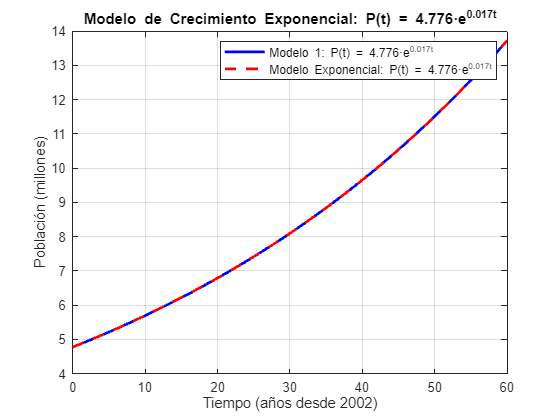


% Convertimos a función numérica
P_func = matlabFunction(P_ts);

% Rango de tiempo (0 a 60 años)
t_vals = linspace(0, 60 , 300);
P_vals = P_func(t_vals);


%% MODELO EXPONENCIAL (Primer MODELO - 2002-2008)
% Datos iniciales
C4 = 4.776;        % P(0)
t4 = 6;           % Tiempo en años para P(6)
P_t4 = 5.308;       % P(6)

% Calcular la tasa k4 a partir de P(1)=C4*exp(k4*t4)
k4 = round(log(P_t4/C4)/t4, 4);

% Definir la función exponencial
P4 = @(t) C4 * exp(k4*t);

% Dominios para evaluar el modelo exponencial
t_expo = linspace(0, 60, 100); % de 0 a 50 años (desde 2002)
Pt4 = P4(t_expo);

% Graficar modelo exponencial
figure;
plot(t_expo, Pt4, 'b-', 'LineWidth', 2);
hold on
plot(t_vals, P_vals,'r--', 'LineWidth', 2)
grid on
xlabel('Tiempo (años desde 2002)')
ylabel('Población (millones)')
legend('Modelo 1: P(t) = 4.776·e^{0.017t} ','Modelo Exponencial: P(t) = 4.776·e^{0.017t}');
title('Modelo de Crecimiento Exponencial: P(t) = 4.776·e^{0.017t}')
hold off

## Modelo Poblacional #2.

primer modelo (1996-2008) 

población inicial de 2002 p(0)= 4.274

r  = 0.018

**Función #2**


$$p\left(t\right)={4\ldotp 274*e}^{0\ldotp 018*t}$$


- Solucion por el metodo de Laplace


$$\frac{\textrm{dp}}{\textrm{dt}}=\textrm{kp}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;p\left(o\right)=4\ldotp 274$$



$$\frac{\textrm{dp}}{\textrm{dt}}\;-0\ldotp 018p\;=0\;\;\;\Rightarrow \;\;L\left\lbrace \frac{\textrm{dp}}{\textrm{dt}}\right\rbrace -0\ldotp 018L\;\left\lbrace p\right\rbrace =L\left\lbrace 0\right\rbrace$$



$$s\;p\left(s\right)\;-\;4\ldotp 274-0\ldotp 018p\left(s\right)=0$$



$$p\left(s\right)\;\left(s-0\ldotp 018\right)=4\ldotp 274\;\Rightarrow \;\;\;p\left(s\right)=\;\frac{4\ldotp 274}{\left(s-0\ldotp 018\right)}$$



$$P\left(s\right)=L^{-1} \;\left\lbrace \frac{4\ldotp 274}{s-0\ldotp 018}\right\rbrace \;\;\;\Rightarrow \;\;\;\;p\left(t\right)=4\ldotp 274e^{0\ldotp 018*t}$$
 

syms P(t) s r P0 Ps
fprintf('Modelo Poblacional (1996-2008) Solucionado por Laplace:\n');

Modelo Poblacional (1996-2008) Solucionado por Laplace:


% Solucion por el metodo de Laplace
% Definimos la ecuación diferencial
fprintf('Ecuacion Diferencial\n');

Ecuacion Diferencial


dp = diff(P, t);
ode = dp == r * P;
pretty(ode)

 d
-- P(t) == r P(t)
dt




% Aplicamos Laplace a la ecuación diferencial
Laplace_ode = laplace(ode, t, s);
odes = subs(Laplace_ode,[laplace(P(t),t,s),P(0)],[Ps,P0]);
fprintf('Laplace\n');

Laplace


pretty(odes)

Ps s - P0 == Ps r




% Despejamos la funcion P(s)
fprintf('Despejamos P(s)\n');

Despejamos P(s)


P_sol = solve(odes,Ps);
pretty(P_sol)

    P0
- -----
  r - s




% Aplicamos Laplace Inversa

fprintf('Laplace Inversa\n');

Laplace Inversa


P_t = ilaplace(P_sol, s, t);
pretty(P_t)

P0 exp(r t)




%Condiciones Iniciales 

P_0 = 4.274;
r_c = 0.018;

% Reemplazamos los valores iniciales  
P_ts = subs(P_t,[P0,r] , [P_0,r_c] );
fprintf('Reemplazamos valores\n');

Reemplazamos valores


pretty(P_ts)

   / 9 t \
exp| --- | 2137
   \ 500 /
---------------
      500




% Convertimos a función numérica
P_func = matlabFunction(P_ts);

% Rango de tiempo (0 a 60 años)
t_vals = linspace(0, 60 , 300);
P_vals = P_func(t_vals);


%% MODELO EXPONENCIAL (Primer MODELO - 1996-2008)
% Datos iniciales
C4 = 4.274;        % P(0)
t4 = 12;           % Tiempo en años para P(12)
P_t4 = 5.308;       % P(12)


% Calcular la tasa k4 a partir de P(1)=C4*exp(k4*t4)
k4 = round(log(P_t4/C4)/t4, 3)

k4 =    0.018000000000000



% Definir la función exponencial
P4 = @(t) C4 * exp(k4*t);

% Dominios para evaluar el modelo exponencial
t_expo = linspace(0, 60, 100); % de 0 a 50 años (desde 1996)
Pt4 = P4(t_expo);

% Graficar modelo exponencial
figure;
plot(t_expo, Pt4, 'b-', 'LineWidth', 2);
hold on
plot(t_vals, P_vals,'r--', 'LineWidth', 2)
grid on;
xlabel('Tiempo (años desde 2002)')
ylabel('Población (millones)')
legend('Modelo 1: P(t) = 4.274·e^{0.018t} ','Modelo Exponencial: P(t) = 4.274·e^{0.018t}');
title('Modelo de Crecimiento Exponencial: P(t) = 4.274·e^{0.018t}')

hold off;

**Modelo Logistico #1.**

#### **Solucion del  Modelo 1984 - 1985 por varibales separables   **


$$P\left(0\right)=3\ldotp 279$$



$$P\left(1\right)=3\ldotp 355$$


$\textrm{Pmax}=8\ldotp 5$ = k

r = 0.03757


$$P\left(t\right)=\frac{5\ldotp 338}{e^{-0\ldotp 03757*t} +0\ldotp 628}$$


**Solucion del  Modelo 1984 - 1985 por Laplace**


$$p_{\left(t\right)} =\;\frac{1}{\frac{1}{8\ldotp 5}\;+\;e^{-0\ldotp 03757t} \;\left(\frac{1}{3\ldotp 279}\;-\;\frac{1}{8\ldotp 5}\right)}$$



$$p_{\left(t\right)} =\;\frac{1}{0\ldotp 1176+\;{0\ldotp 1873*e}^{-0\ldotp 03757t} }$$


syms P(t) s r P0 Ps k u U(t) Us U0
% Solucion por el metodo de Laplace
% Definimos la ecuación diferencial

dp = diff(P, t);

% Sustitucion de Bernoulli
du = diff(U,t);
P_subs = 1/U;
dP_subs = -1/U^2 * du;


ode = dp -r * P == -(r * P^2)/k;
odeu = (subs(ode,[dp,P],[dP_subs,P_subs]))/(-1/U^2);
fprintf('Modelo Logístico lineal\n');

Modelo Logístico lineal


pretty(odeu);

      /  d             \
      | -- U(t)        |
    2 | dt          r  |    r
U(t)  | ------- + ---- | == -
      |      2    U(t) |    k
      \  U(t)          /





% Aplicamos Laplace a la ecuación diferencial
Laplace_ode = laplace(odeu, t, s);
odes = subs(Laplace_ode,[laplace(U(t),t,s),U(0)],[Us,U0]);


% Despejamos la funcion P(s)
U_sol = solve(odes,Us);
fprintf('Aplicamos Laplace y despejamos U(s)\n');

Aplicamos Laplace y despejamos U(s)


pretty(U_sol)

      r
U0 + ---
     k s
--------
  r + s




% Aplicamos Laplace Inversa

U_t = ilaplace(U_sol, s, t)

$$U\_t = \frac{1}{k}+\frac{{\mathrm{e}}^{-r\,t}\,\left(U_{0}\,k-1\right)}{k}$$

fprintf('Aplicamos Laplace Inversa Para hallar U(t)\n');

Aplicamos Laplace Inversa Para hallar U(t)


pretty(U_t)

1   exp(-r t) (U0 k - 1)
- + --------------------
k             k




fprintf('Volvemos a la expresion original es terminos de P(t)\n');

Volvemos a la expresion original es terminos de P(t)


P_t = 1/(subs(U_t,(U0),(1/P0)))

$$P\_t = \frac{1}{\frac{1}{k}+\frac{{\mathrm{e}}^{-r\,t}\,\left(\frac{k}{P_{0}}-1\right)}{k}}$$


pretty(P_t)

            1
------------------------
              /  k     \
    exp(-r t) | -- - 1 |
1             \ P0     /
- + --------------------
k             k





%Condiciones Iniciales 

P_0 = 3.279;
r_0 = 0.03757;
k_0 = 8.5;

% Reemplazamos los valores iniciales  
P_ts = subs(P_t,[P0,r,k] , [P_0,r_0,k_0] );

fprintf('Modelo Logistico #1 por el metodo de Laplace \n');

Modelo Logistico #1 por el metodo de Laplace 


pretty(P_ts)

             1
--------------------------
   /   3757 t \
exp| - ------ | 10442
   \   100000 /          2
--------------------- + --
        55743           17




% Convertimos a función numérica
P_func = matlabFunction(P_ts);

% Rango de tiempo (0 a 50 años)
t_vals = linspace(0, 60 , 300);
P_vals = P_func(t_vals);


% Graficar modelo
figure;
hold on
plot(t_vals, P_vals,'r', 'LineWidth', 2)
grid on
xlabel('Tiempo (años desde 1984)')
ylabel('Población (millones)')
title('Modelo Logistico Num 1')

%% MODELO LOGÍSTICO
% Parámetros obtenidos en el proceso de separación de variables:
% Se tiene la solución en la forma: P(t)=5.338/(exp(-0.0412*t)+0.628)
k_cap = 8.5;     % Capacidad de carga (no se usa directamente en la fórmula final)
A = 0.628;       % Constante determinada a partir de P(0)=3.279
r = 0.03757;      % Tasa de crecimiento
num = 5.338;     % Producto de 8.5*A

% Definir la función logística
P_log = @(t) num ./ (exp(-r*t) + A);

% Dominios para evaluar el modelo logístico
t_log = linspace(0, 60, 100);
P_log_values = P_log(t_log);
plot(t_log, P_log_values, 'b--', 'LineWidth', 2);
legend('Modelo por Laplace P(t)=1/(0.187*e^{-0.03757t}+0.117) ','Modelo por variables seperables: P(t)=5.338/(e^{-0.03757t}+0.628)');
hold off;

**Modelo Logistico #2.**

#### **Solucion del  Modelo 2000-2001 por varibales separables **


$$P\left(0\right)=4\ldotp 607$$



$$P\left(1\right)=4\ldotp 693$$


$\textrm{Pmax}=8$ = k

r = 0.0441


$$P\left(t\right)=\frac{10\ldotp 856}{e^{-0\ldotp 0441*t} +1\ldotp 357}$$


**Solucion del  Modelo 2000-2001 por Laplace**


$$p_{\left(t\right)} =\;\frac{1}{\frac{1}{8}\;+\;e^{-0\ldotp 0441t} \;\left(\frac{1}{4\ldotp 607}\;-\;\frac{1}{8}\right)}$$



$$p_{\left(t\right)} =\;\frac{1}{0\ldotp 125+\;{0\ldotp 092*e}^{-0\ldotp 03757t} \;}$$


syms P(t) s r P0 Ps k u U(t) Us U0
% Solucion por el metodo de Laplace
% Definimos la ecuación diferencial

dp = diff(P, t);

% Sustitucion de Bernoulli
du = diff(U,t);
P_subs = 1/U;
dP_subs = -1/U^2 * du;


ode = dp -r * P == -(r * P^2)/k;
odeu = (subs(ode,[dp,P],[dP_subs,P_subs]))/(-1/U^2);
fprintf('Modelo Logístico lineal\n');

Modelo Logístico lineal


pretty(odeu);

      /  d             \
      | -- U(t)        |
    2 | dt          r  |    r
U(t)  | ------- + ---- | == -
      |      2    U(t) |    k
      \  U(t)          /





% Aplicamos Laplace a la ecuación diferencial
Laplace_ode = laplace(odeu, t, s);
odes = subs(Laplace_ode,[laplace(U(t),t,s),U(0)],[Us,U0]);


% Despejamos la funcion P(s)
U_sol = solve(odes,Us);
fprintf('Aplicamos Laplace y despejamos U(s)\n');

Aplicamos Laplace y despejamos U(s)


pretty(U_sol)

      r
U0 + ---
     k s
--------
  r + s




% Aplicamos Laplace Inversa

U_t = ilaplace(U_sol, s, t)

$$U\_t = \frac{1}{k}+\frac{{\mathrm{e}}^{-r\,t}\,\left(U_{0}\,k-1\right)}{k}$$

fprintf('Aplicamos Laplace Inversa Para hallar U(t)\n');

Aplicamos Laplace Inversa Para hallar U(t)


pretty(U_t)

1   exp(-r t) (U0 k - 1)
- + --------------------
k             k




fprintf('Volvemos a la expresion original es terminos de P(t)\n');

Volvemos a la expresion original es terminos de P(t)


P_t = 1/(subs(U_t,(U0),(1/P0)))

$$P\_t = \frac{1}{\frac{1}{k}+\frac{{\mathrm{e}}^{-r\,t}\,\left(\frac{k}{P_{0}}-1\right)}{k}}$$


pretty(P_t)

            1
------------------------
              /  k     \
    exp(-r t) | -- - 1 |
1             \ P0     /
- + --------------------
k             k





%Condiciones Iniciales 

P_0 = 4.607;
r_0 = 0.0441;
k_0 = 8;

% Reemplazamos los valores iniciales  
P_ts = subs(P_t,[P0,r,k] , [P_0,r_0,k_0] );

fprintf('Modelo Logistico #1 por el metodo de Laplace \n');

Modelo Logistico #1 por el metodo de Laplace 


pretty(P_ts)

           1
-----------------------
   /   441 t \
exp| - ----- | 3393
   \   10000 /        1
------------------- + -
       36856          8




% Convertimos a función numérica
P_func = matlabFunction(P_ts);

% Rango de tiempo (0 a 50 años)
t_vals = linspace(0, 60 , 300);
P_vals = P_func(t_vals);


% Graficar modelo
figure;
hold on
plot(t_vals, P_vals,'r', 'LineWidth', 2)
grid on
xlabel('Tiempo (años desde 1984)')
ylabel('Población (millones)')
title('Modelo Logistico Num 1')

%% MODELO LOGÍSTICO
% Parámetros obtenidos en el proceso de separación de variables:
k_cap = 8;     % Capacidad de carga (no se usa directamente en la fórmula final)
A = 1.357;       % Constante determinada a partir de P(0)=3.279
r = 0.0441;      % Tasa de crecimiento
num = 10.856;     % Producto de 8.5*A

% Definir la función logística
P_log = @(t) num ./ (exp(-r*t) + A);

% Dominios para evaluar el modelo logístico
t_log = linspace(0, 60, 100);
P_log_values = P_log(t_log);
plot(t_log, P_log_values, 'b--', 'LineWidth', 2);
legend('Modelo por Laplace P(t)=1/(0.092*e^{-0.0441t}+0.125) ','Modelo por variables seperables: P(t)=10.856/(e^{-0.0441t}+1.357)');
hold off;

**Conclusiones**

En este proyecto se pudo evidenciar el primer acercamiento a la importancia del cálculo a lo largo del desarrollo humano, y cómo, por medio de procedimientos algebraicos, cálculo diferencial e integral, se puede desarrollar una ecuación diferencial que nos permite predecir la población en determinado ambiente. Esto es de suma importancia, ya que tiene gran influencia en ámbitos como la biología, ecología, economía y sociología.

Para llevarlo a cabo, se tomó una población que se caracterizara por tener una alta calidad de vida a lo largo de la historia, con pocos enfrentamientos militares y buena estabilidad en términos económicos, educativos, políticos y de respeto a los derechos humanos. Todo esto permite que un modelo exponencial o logístico sea más preciso al determinar la población en un determinado año.

En el caso del modelo exponencial, se obtuvieron resultados con un rango de precisión del 4 % al 24 % para el año 2020. Esto dependía en gran parte de los valores iniciales utilizados para resolver una función explícita. Se observó que el porcentaje de precisión estaba más ligado al segundo dato que requiere el modelo exponencial, es decir, que el porcentaje variaba según qué tan alejado en años estaba el segundo dato respecto al año que se quería predecir, sin importar cuán distante estuviera el año inicial.

No obstante, dado que este modelo exponencial predice un crecimiento continuo, se implementó una ecuación logística, la cual ofrece mayor precisión al incluir un factor limitante. En el caso de Canadá, se puede deducir que solo el 10 % del territorio es altamente habitable y cultivable debido a sus climas extremos, que alcanzan temperaturas de hasta –50 °C. Por ello, nuestro factor limitante para el modelo logístico será primordialmente la temperatura.

En el desarrollo de este modelo se evidenció una mayor precisión, ya que el rango de error se redujo a entre 1.07 % y 2.84 %. Para ello, se analizó una predicción coherente del límite poblacional y se concluyó que el modelo es mucho más preciso si se toman valores en donde la población se encuentra en la transición de la curva ascendente a descendente.

En términos de desarrollo, la ecuación de Laplace permitió resolver el modelo exponencial de una manera más sencilla. Por el contrario, el modelo logístico, al no ser una ecuación lineal, presentó un procedimiento más complejo para su resolución; sin embargo, una opción eficiente para resolverlo fue mediante el método de variables separables.

- Si quieres explorar cómo funcionan los modelos poblacionales, ingresa al siguiente enlace: [https://team-papitas-fritas.netlify.app/](https://team-papitas-fritas.netlify.app/)

Escanea el siguiente codigo: